# **pEllipticPi**

Legendre form of the elliptic integral of the third kind

## Definition


$$\Pi \left(\phi ,\nu \left|m\right.\right)\equiv \int_0^{\phi } \frac{\;\;d\theta \;}{\left(1-\nu \;{\mathrm{sin}}^2 \theta \right)\sqrt{1-m\;\sin^2 \theta }}$$



$$\Pi \left(\phi ,\nu ,k\right)\equiv \Pi \left(\phi ,\nu \left|k^2 \right.\right)$$


where $\phi \;$is the argument, *k *is the modulus,  *m *is the parameter.

Domain: $1-m\sin^2 \phi \ge 0\;$and $1-\nu \;\sin^2 \phi \ge 0$ . If $-\infty <m\le 1$(or $\left.|k|\le 1\right)$ and and $-\infty <\nu <1$ then $-\infty \le \phi \le \infty$ (quasi-periodic function). If $m>1$ (or $k>1$) then  $\left|\phi \right|<\sin^{-1} \left(1/\sqrt{m}\right)\;$and $\nu \le m$. If $\nu \ge 1$  then $\left|\phi \right|<\sin^{-1} \left(1/\sqrt{\nu }\right)$ and $m\le \nu$. For the specified domain, the  codomain is the set of real numbers.

Basic features:

$\Pi \left(-\phi ,\nu \left|m\right.\right)=-\Pi \left(\phi ,\nu \left|m\right.\right)$   (odd)

 $\Pi \left(n\pi \pm \phi ,\nu \left|m\right.\right)=2n\;\Pi \left(\nu |m\right)\pm \Pi \left(\phi ,\nu \left|m\right.\right),\;\;\;\left|\phi \right|\le \pi /2$  (quasi-periodic)

Special values:

$\Pi \left(0,\nu \left|m\right.\right)=0$,   $\Pi \left(\frac{\pi }{2},\nu \left|m\right.\right)=\Pi \left(\nu \left|m\right.\right)$

$\Pi \left(\phi ,0\left|0\right.\right)=\phi$,   $\Pi \left(\phi ,0\left|1\right.\right)={\mathrm{gd}}^{-1} \phi$,   $\Pi \left(\phi ,1\left|0\right.\right)=\tan \phi$,  $\Pi \left(\phi ,1\left|1\right.\right)=\frac{1}{4}\mathrm{ln}\frac{1+\mathrm{sin}\phi }{1-\mathrm{sin}\phi }+\frac{1}{2}\frac{\mathrm{sin}\;\phi }{{\mathrm{cos}}^2 \phi }$

 $\Pi \left(\phi ,-\infty |m\right)=0$,   $\Pi \left(\phi ,0\left|m\right.\right)=F\left(\phi |m\right)$,   $\Pi \left(\phi ,1\left|m\right.\right)=F\left(\phi \left|m\right.\right)-\frac{E\left(\phi \left|m\right.\right)-\;\mathrm{tan}\phi \sqrt{1-m{\;\mathrm{sin}}^2 \phi }}{1-m}$ 


$$\Pi \left(\phi ,\nu \left|-\infty \right.\right)=0$$



$$\Pi \left(\phi ,\nu \left|0\right.\right)=\left\lbrace \begin{array}{cc}
\frac{{\mathrm{tanh}}^{-1} \left(\sqrt{\nu -1}\;\tan \phi \right)}{\sqrt{\nu -1}} & \nu >1,\;|\phi |<{\mathrm{tan}}^{-1} \left(1/\sqrt{\nu -1}\right)\\
\frac{\tan^{-1} \left(\sqrt{1-\nu }\;\tan \phi \right)}{\sqrt{1-\nu }} & \nu <1
\end{array}\right.$$



$$\Pi \left(\phi ,\nu \left|1\right.\right)=\frac{1}{1-\nu }\left\lbrace \begin{array}{cc}
{\mathrm{t}\textrm{anh}}^{-1} \sin \phi -\sqrt{\nu }{\tan h}^{-1} \left(\sqrt{\nu }\;\sin \phi \right) & \nu >0,\nu >1\Rightarrow \left|\phi \right|<\sin^{-1} \left(1/\sqrt{\nu }\right)\\
{\textrm{tanh}}^{-1} \sin \phi +\sqrt{-\nu }\tan^{-1} \left(\sqrt{-\nu }\;\sin \phi \right) & \nu <0
\end{array}\right.$$


Identities:


$$\Pi \left(\phi ,\nu \left|m\right.\right)=\Pi \left(\sin \left(\phi \right),\nu \left|m\right.\right),\left|\phi \right|\le \pi /2$$



$$\Pi \left(\phi ,m\left|m\right.\right)=\frac{E\left(\phi \left|m\right.\right)}{1-m}-\frac{m\;\sin \phi \;\cos \phi }{\left(1-m\right)\sqrt{1-m\;\sin^2 \phi }}$$


$F\left(\phi \left|m\right.\right)\;$and $E\left(\phi \left|m\right.\right)\;$are Legendre form of elliptic integrals of the first and the second kind, $\Pi \left(\nu \left|m\right.\right)$is the complete elliptic integrals of the third kind, and ${\textrm{gd}}^{-1} \phi$ is the inverse Gudermannian function .

## Syntax

Y = pEllipticPi(PHI,NU,K)

y = pelPi(phi,nu,k)

Y = mpEllipticPi(PHI,NU,M)

y = mpelPi(phi,nu,m)

## Description

**Y = pEllipticPi(PHI,NU,K)** returns the Legendre form of the elliptic integral of the third kind  $\Pi \left(\phi ,\nu ,k\right)$ for each element of the arrays PHI (the argment), NU (the parameter) and K (the modulus). PHI, NU and K must be real and the same size or any of them can be scalar. **pEllipticPi** is the wrapper function which calls the functions **pelPi** element-wise via the function **ufun3**.

**y = pelPi(phi,k) **returns the value of  the Legendre form of the elliptic integral of the third kind  $\Pi \left(\phi ,\nu ,k\right)$ for the argument phi, the parameter nu and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **pelPi** is the wrapper function which calls the functions **mpelPi**.

**Y = mpEllipticPi(PHI,NU,M)** returns the Legendre form of the elliptic integral of the third kind  $\Pi \left(\phi ,\nu \left|m\right.\right)$  for each element of the arrays PHI (the argument), NU (the parameter) and M (parameter). PHI, NU and M must be real and the same size or any of them can be scalar. **mpEllipticPi** is the wrapper function which calls the functions **mpelPi** element-wise via the function **ufun3**.

**y = mpelPi(phi,nu,m)** returns the value of the Legendre form of the elliptic integral of the third kind $\Pi \left(\phi ,\nu \left|m\right.\right)$ for  the argument phii, the parameter nu and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mpelPi **call the Carlson's function **rd **and** rj **for calculation of $\Pi \left(\phi ,\nu \left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
nu = 0.5;
phi = 1;
[pelPi(phi,nu,k), pEllipticPi(phi,nu,k), mpelPi(phi,nu,k^2), mpEllipticPi(phi,nu,k^2)]

ans =    1.228014414316221   1.228014414316221   1.228014414316221   1.228014414316221


Accuracy. 

fprintf('%.16g\n',mpelPi(1,1/2,1/4)) 

1.228014414316221


%Maple 1.228014414316220_64

fprintf('%.16g\n',mpelPi(pi/4,-2,-4)) 

0.499847217662754


% Maple 0.499847217662754_041

Special values

m = -0.5;
nu = 0.5;
phi = pi/9;
mpEllipticPi(-phi,nu,m) + mpEllipticPi(phi,nu,m)

ans = 0

mpEllipticPi(0,nu,m)

ans = 0

disp(mpEllipticPi(pi/2,nu,m) - mEllipticPi(nu,m))

     0



pEllipticPi(phi,-inf,m)

ans = 0

disp(pEllipticPi(phi,1,1)-...
    1/4*log((1+sin(phi))/(1-sin(phi)))-1/2*sin(phi)/cos(phi)^2)

     5.551115123125783e-17



disp(pEllipticPi(phi,0,m)-pEllipticF(phi,m))

     0



disp(pEllipticPi(phi,1,0)-tan(phi))

     0



disp(pEllipticPi(phi,0,1)-igd(phi)) % igd is inverse Gudermann function

     0



Identities

m=-10^4;
nu = -2;
phi = 0.499*pi; % |phi|<=pi/2
disp(mpelPi(phi,nu,m) - melPi(sin(phi),nu,m))

    -3.469446951953614e-17



phi = pi/3; % |phi|<=pi/2
k = 0.5; % |k|<=1
nu = -8;
n = 2;
disp(pelPi(phi+n*pi,nu,k)-(pelPi(phi,nu,k)+2*n*elPi(nu,k))) % periodicity

     0



phi = pi/3;
m = 1/2;
disp(mpelPi(phi,m,m)-(mpelE(phi,m)/(1-m)-m*sin(phi)*cos(phi)/(1-m)/sqrt(1-m*sin(phi)^2)))

     0



**Vector input**

format short
k = 0.5;
NU = [-2, -1,1/2,1/4];
PHI = [pi/3, pi/4, 1, pi/2];
disp(pEllipticPi(PHI,NU,k) - EllipticPi(sin(PHI),NU,k))

   1.0e-15 *

   -0.1110         0         0         0



PHI = [pi/3, pi/4, 1, pi/2];
M  = [-1 -2 -3 -4];
disp(mpEllipticPi(PHI,M,M)-...
    (mpEllipticE(PHI,M)./(1-M)-M.*sin(PHI).*cos(PHI)./(1-M)./sqrt(1-M.*sin(PHI).^2)))

   1.0e-15 *

         0         0         0    0.1110



disp(mpEllipticPi(PHI',0,M')-mpEllipticF(PHI',M'))

     0
     0
     0
     0



**Matrix input**

PHI = [pi/6 pi/4 3*pi/8; -pi/6 -pi/4 -3*pi/8];
M = [1/4 1 1/9; -0.1 0.2 -1e10];
nu = -2;
disp(mpEllipticPi(PHI,nu,M) - mEllipticPi(sin(PHI),nu,M))

   1.0e-15 *

   -0.0555   -0.2220   -0.1110
   -0.1665   -0.1110    0.0000



## **Graphs **

**Example 1**

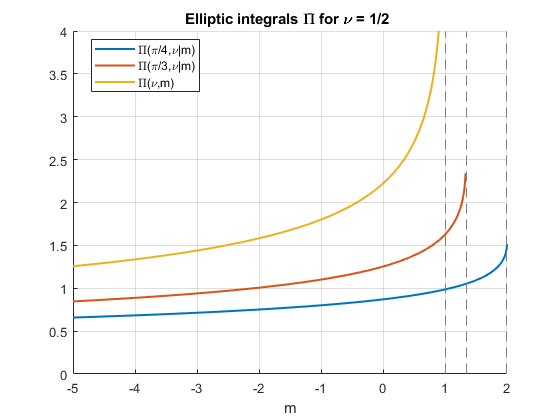

figure
hold on
nu = 1/2;
fplot(@(m)mpEllipticPi(pi/4,nu, m),'LineWidth',1.5)
fplot(@(m)mpEllipticPi(pi/3,nu, m),'LineWidth',1.5)
fplot(@(m)mEllipticPi(nu,m),'LineWidth',1.5)
xlabel('m')
grid on
ylim([0 4])
title('Elliptic integrals \Pi for \nu = 1/2 ')
legend('\Pi(\pi/4,\nu|m)', '\Pi(\pi/3,\nu|m)', '\Pi(\nu,m)', 'Location', 'Best')
hold off

**Example 2**

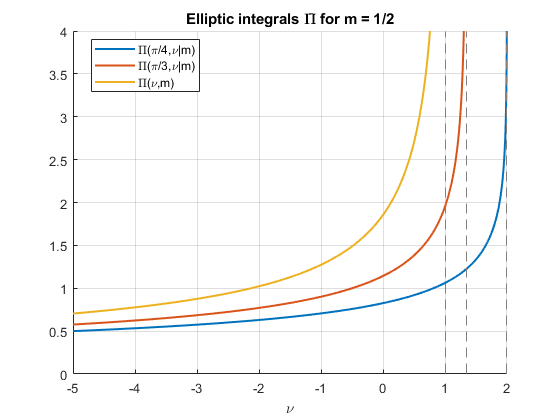

figure
hold on
m = 1/2;
fplot(@(nu)mpEllipticPi(pi/4,nu, m),'LineWidth',1.5)
fplot(@(nu)mpEllipticPi(pi/3,nu, m),'LineWidth',1.5)
fplot(@(nu)mEllipticPi(nu,m),'LineWidth',1.5)
xlabel('\nu')
grid on
ylim([0 4])
title('Elliptic integrals \Pi for m = 1/2')
legend('\Pi(\pi/4,\nu|m)', '\Pi(\pi/3,\nu|m)', '\Pi(\nu,m)', 'Location', 'Best')
hold off

**Example 3**

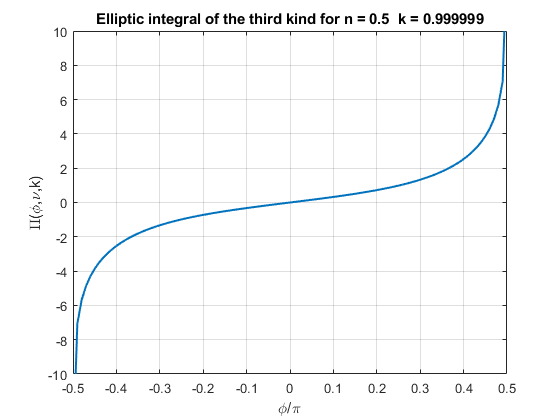

figure
phi=-1.5:0.01:1.5;
nu = 0.5;
k = 0.999999;
plot(phi,pEllipticPi(pi*phi,nu,k),'LineWidth',1.5)
xlabel('\phi/\pi')
ylabel('\Pi(\phi,\nu,k)')
%xlim([-1.1 1.1])
ylim([-10 10])
title(sprintf('Elliptic integral of the third kind for n = %g  k = %g',nu,k))
grid on

**Example 4**

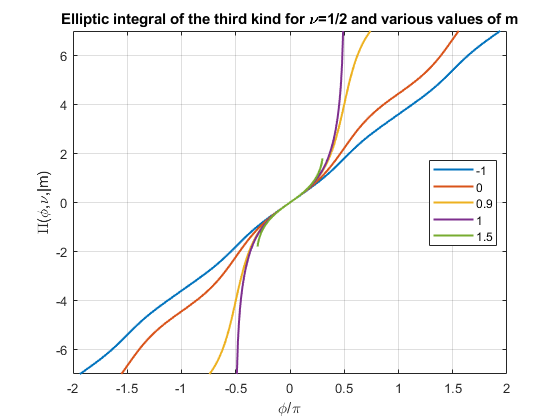

figure
PHI = -2:0.01:2;
nu = 0.5;
M = [-1,0,0.9, 1,1.5];
SN = zeros(length(M),length(PHI));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mpEllipticPi(pi*PHI,nu,M(i));
end
plot(PHI,SN,'LineWidth',1.5)
axis([min(PHI) max(PHI) -7 7])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral of the third kind for \nu=1/2 and various values of m')
xlabel('\phi/\pi')
ylabel('\Pi(\phi,\nu,|m)')

**Example 5**

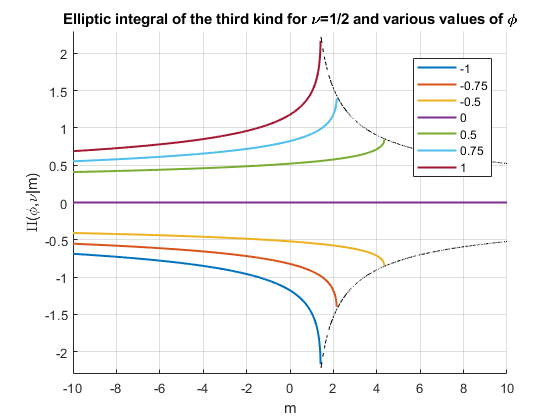

figure
hold on
nu = 0.5;
M = -10:0.01:10;
X = [-1,-0.75,-0.5,0,0.5,0.75,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mpEllipticPi(X(i),nu,M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -2.3 2.3])
M = 0:0.01:10;
D = mEllipticPi(1./sqrt(abs(M)),nu,M);
plot(M,D,'k-.')
plot(M,-D,'k-.')
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral of the third kind for \nu=1/2 and various values of \phi')
xlabel('m')
ylabel('\Pi(\phi,\nu|m)')
hold off

**Example 6**

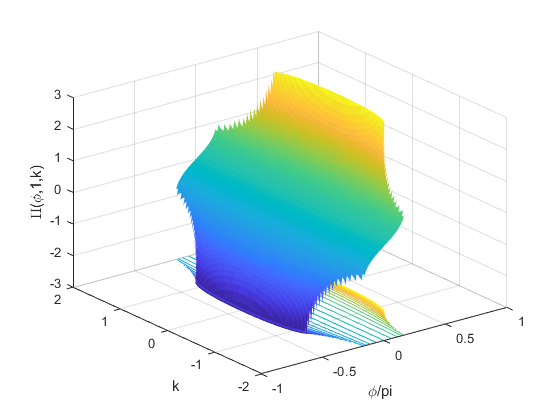

figure
phi=-1:0.01:1;
k=-2:0.01:2;
nu = 1;
[PHI,K]=meshgrid(phi,k);
hs=surfc(PHI,K,pEllipticPi(pi*PHI,nu,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
caxis([-3 3])
view(3);
xlabel('\phi/pi')
ylabel('k')
zlabel(sprintf('%s%g%s','\Pi(\phi,',nu,',k)'))
zlim([-3 3])
grid on

**Example 7**

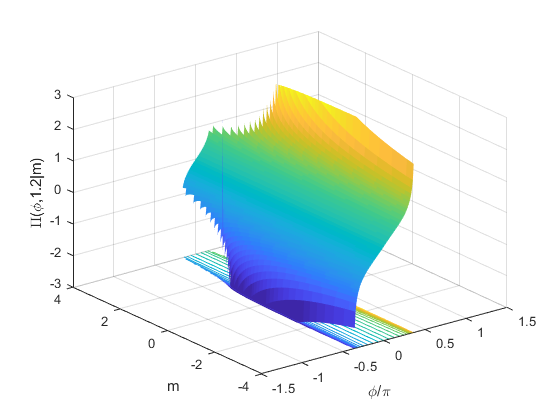

figure
phi=-1.5:0.01:1.5;
m=-4:0.01:4;
nu = 1.2;
[PHI,M]=meshgrid(phi,m);
hs=surfc(PHI,M,mpEllipticPi(pi*PHI,nu,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
view(3)
caxis([-3 3])
xlabel('\phi/\pi')
ylabel('m')
zlabel(sprintf('%s%g%s','\Pi(\phi,',nu,'|m)'))
zlim([-3 3])
grid on

**Example 8**

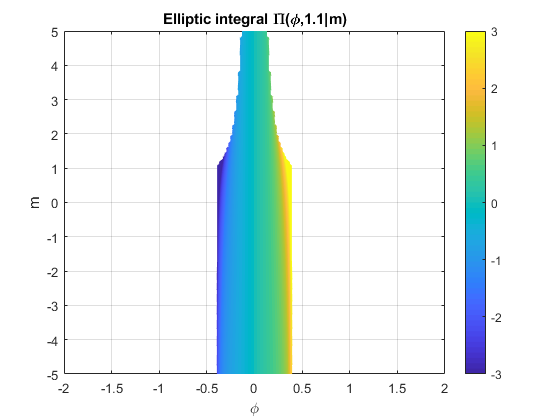

figure
nu = 1.1;
f = @(phi,m)mpEllipticPi(pi*phi,nu,m);
fcontour(f,[-2 2 -5 5],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title(sprintf('Elliptic integral %s(%s,%g|m)','\Pi','\phi',nu))
colorbar
xlabel('\phi')
ylabel('m')
grid on

**Example 9**

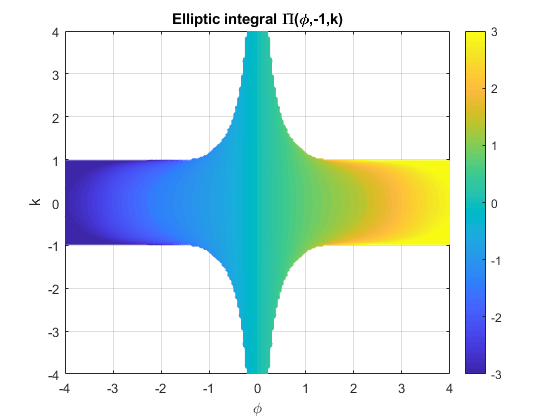

figure
nu = -1;
f = @(phi,k)pEllipticPi(phi,nu,k);
fcontour(f,[-4 4 -4 4],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral \Pi(\phi,-1,k)')
colorbar
xlabel('\phi')
ylabel('k')
grid on

**Example 10**

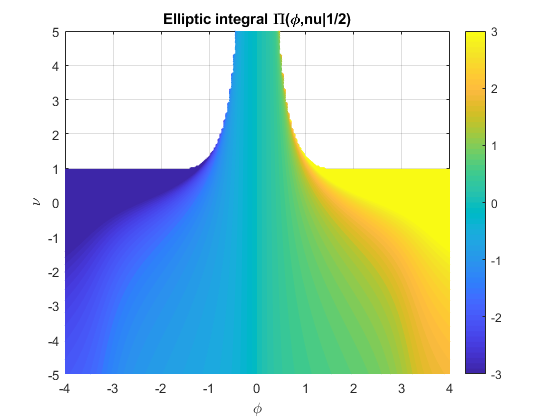

figure
m = 0.5;
f = @(phi,nu)mpEllipticPi(phi,nu,m);
fcontour(f,[-4 4 -5 5],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral \Pi(\phi,nu|1/2)')
colorbar
xlabel('\phi')
ylabel('\nu')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

[Higher Transcendental Functions](http://apps.nrbook.com/bateman/Vol2.pdf) 

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

[3] A. Erd´elyi et al., Higher Transcendental Functions Vol. II, California Institute of

Technology - Bateman Manuscript Project, 1953-1955 McGraw-Hill Inc. 

[4] E.Jahnke, F. Emde, Tables of Functions, 4th ed, Dover,  1945

## See Also